# Summierte Trapezregel

Wir untersuchen die summierte Trapezregel zur Annäherung eines Integrals $I=\int_0^1 f(x)\, dx$, also

     $T(h)=h\big[\frac12 f(0) +f(t_1)+\ldots+f(t_{n-1})+\frac12 f(1)\big]$ , mit $t_j=jh$, $h=1/n$.

Als Beispiele betrachten wir:

    1.   $f(x)=0.25\pi^2 x\cos(0.5 \pi x)+0.5\pi e^{0.5\pi x}$    (Beispiel Buch umskaliert auf $[0,1]$)

    2.   $f(x)= x e^x$      (glatte Funktion)

    3.  $f(x)= \sqrt{x}$       (nicht glatt an der Stelle $x=0$)

    4.  $f(x)= |x-\frac13|^a, \quad a \in (0,1).$     (nicht glatt an der Stelle $x=\frac{1}{3}$)

    5.   $ f(x)= x^2 |x-\frac13|$       (nicht glatt an der Stelle $x=\frac{1}{3}$)

    6.   $f(x)= x^{\frac14}$           (nicht glatt an der Stelle $x=0$)

    7.  $f(x)= \sin^2(\pi x)$      (periodische Funktion mit  $f^{(k)}(0)=f^{(k)}(1)=0, ~~k=1,3,\dots.$)

Für diese Bespiele kann analytisch der exakte Wert des Integrals $I$ berechnet werden.

Durch Angabe von **choice** $\in \{1,2,\ldots,7\}$ wird eins dieser Bespiele gewählt. 

Für** choice**=4 muss auch der Wert des Parameters $a \in (0,1)$ gesetzt werden.

choice=1

choice = 1

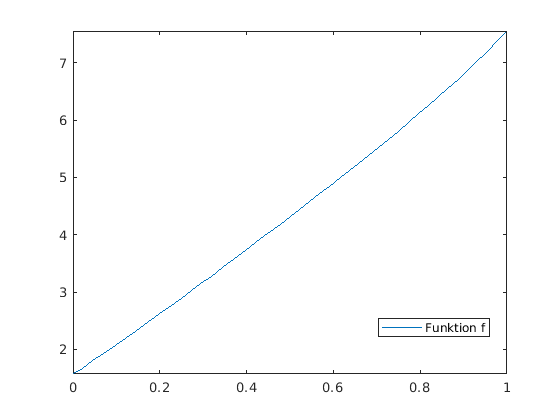

a=0.6;
[f,Iexakt]= Beispiel(choice,a);
fplot(f,[0 1]);
legend('Funktion f', 'Location','best');

Für $n=4,8,16,32,64$ werden die Trapezsumme  $T(1/n)$ und der Fehler $E_n:=|T(1/n)-I|$  berechnet und  gezeigt.

Außerdem wird der Fehlerreduktionsfaktor $E_n/E_{2n}$ berechnet.

# Aktivität:

Sie können den Parameter** choice** variieren und ggf. eigene Beispiele hinzufügen. Beobachten Sie die Fehlerreduktionsfaktoren. 

d=4; % Anzahl der Verdoppelungen von n
Trapezsumme=zeros(d+1,1);
for k=1:d+1
    n=2^(k+1);
    h=1/n;
    T= 0.5*(f(0) + f(1));
    for i=1:n-1
        T= T + f(i*h);
    end
    Trapezsumme(k)= h*T;
end
format long;
Trapezsumme

Trapezsumme =    4.396927734683951
   4.385239200472051
   4.382268326300528
   4.381522565172672
   4.381335934786041


format shorte;
Fehler=abs(Trapezsumme - Iexakt)

Fehler =    1.5654e-02
   3.9655e-03
   9.9462e-04
   2.4886e-04
   6.2227e-05


Faktor=zeros(d,1);
for i=1:d
    Faktor(i)=Fehler(i)/Fehler(i+1);
end
format short;
Faktor

Faktor =     3.9476
    3.9869
    3.9967
    3.9992


function [f,Iexakt]= Beispiel(bsp,a)
switch bsp
    case 1
        f= @(x) 0.25*pi^2*x.*cos(0.5*pi.*x) + 0.5*pi*exp(0.5*pi.*x);
        Iexakt= pi/2 + exp(0.5*pi) - 2;
    case 2
        f= @(x) x.*exp(x);
        Iexakt= 1;
    case 3
        f= @(x) sqrt(x);
        Iexakt= 2/3;
    case 4
        f= @(x) (abs(x-1/3)).^(a);
        Iexakt= 1/(a+1)*((2/3)^(a+1) + (1/3)^(a+1));
    case 5
        f= @(x) abs(x-1/3).*x.^2;
        Iexakt= (3 + 29/36)/27;
    case 6
        f= @(x) x.^(0.25);
        Iexakt= 0.8;
    case 7
        f= @(x) sin(pi.*x).^2;
        Iexakt= 1/2;
end

end